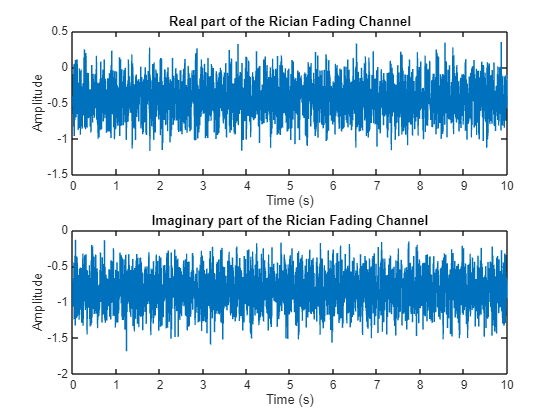

function [h] = ricianFading(M, N, fd, Ts, K_factor)
    % M = number of multi-paths in the channel
    % N = number of samples to generate
    % fd = maximum Doppler frequency
    % Ts = sampling period
    % K_factor = K factor in dB (ratio of direct path power to scattered path power)

    % Convert K-factor from dB to linear scale
    K_linear = 10^(K_factor / 10);

    % Phases for LOS component
    phi_LOS = 2 * pi * rand(1);  % Uniform distribution for LOS phase

    % Generate uniformly distributed random phases for NLOS components
    a = 0;
    b = 2 * pi;
    alpha = a + (b - a) * rand(1, M);
    beta = a + (b - a) * rand(1, M);
    theta = a + (b - a) * rand(1, M);

    m = 1:M;  % Indices for multipaths

    h_re = zeros(1, N);
    h_im = zeros(1, N);

    for n = 1:N
        % NLOS components
        x = cos(((2 .* m - 1) * pi + theta) / (4 * M));
        h_nlos_re = sum(cos(2 * pi * fd * x * n * Ts + alpha));
        h_nlos_im = sum(sin(2 * pi * fd * x * n * Ts + beta));

        % LOS component (scaled by sqrt(K/(K+1)) for power ratio)
        h_los_re = sqrt(K_linear / (K_linear + 1)) * cos(phi_LOS);
        h_los_im = sqrt(K_linear / (K_linear + 1)) * sin(phi_LOS);

        % Total complex channel coefficient
        h_re(n) = (h_los_re + h_nlos_re / sqrt(M * (K_linear + 1)));
        h_im(n) = (h_los_im + h_nlos_im / sqrt(M * (K_linear + 1)));
    end

    h = h_re + 1i * h_im;  % Complex Rician fading envelope
end

% Test program to generate Rician fading samples
clc; clear;

M = 15;          % Number of multipaths
N = 10^5;        % Number of samples to generate
fd = 100;        % Maximum Doppler frequency (Hz)
Ts = 0.0001;     % Sampling period in seconds
K_factor = 9;    % K-factor in dB

% Generate Rician fading samples
h = ricianFading(M, N, fd, Ts, K_factor);
h_re = real(h);  % Real part of the channel
h_im = imag(h);  % Imaginary part of the channel

% Plot real and imaginary parts
figure;
subplot(2,1,1);
plot([0:N-1] * Ts, h_re);
title('Real part of the Rician Fading Channel');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(2,1,2);
plot([0:N-1] * Ts, h_im);
title('Imaginary part of the Rician Fading Channel');
xlabel('Time (s)');
ylabel('Amplitude');

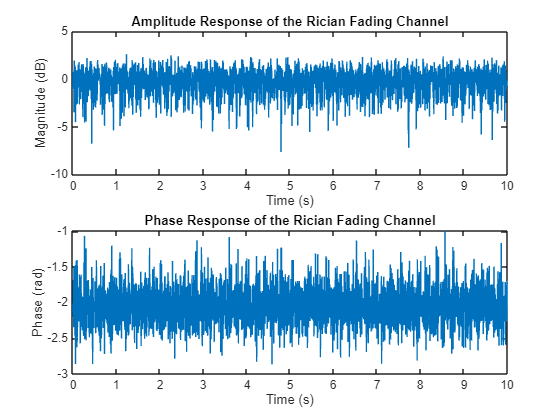


% Plot magnitude and phase
figure;
subplot(2,1,1);
plot([0:N-1] * Ts, 10 * log10(abs(h)));
title('Amplitude Response of the Rician Fading Channel');
xlabel('Time (s)');
ylabel('Magnitude (dB)');

subplot(2,1,2);
plot([0:N-1] * Ts, angle(h));
title('Phase Response of the Rician Fading Channel');
xlabel('Time (s)');
ylabel('Phase (rad)');